data = struct;
data.deltap = 1; 
data.pm = 996;
data.vsm =1e-6;
data.L = 0.6;
data.d = 0.002;
data.g = 9.81;

data.R = (128*data.vsm*data.L)/(pi()*data.d^4);
data.as = (pi()*data.d^2)/4;
data.ct = sqrt(data.L/data.g);
data.damp = (data.as*data.R)/(2*data.g*data.ct);
data

data = struct with fields:
    deltap: 1
        pm: 996
       vsm: 1.0000e-06
         L: 0.6000
         d: 0.0020
         g: 9.8100
         R: 1.5279e+06
        as: 3.1416e-06
        ct: 0.2473
      damp: 0.9892



a = data.ct^2;
b = 2*data.damp*data.ct;
c = 1;
d = data.deltap/(data.pm*data.g);

syms y(x)
ode = a*diff(y,x,2) + b*diff(y,x) + c*y - d == 0

$$ode(x) = \frac{20\,\frac{\partial^{2}}{\partial x^{2}}y\left(x\right)}{327}+\frac{160\,\frac{\partial }{\partial x}y\left(x\right)}{327}+y\left(x\right)-\frac{7551815446785941}{73786976294838206464}=0$$

Dy = diff(y,x,1);
cond1 = y(0) == 0;
cond2 = Dy(0) == 0;
conds = [cond1 cond2]

$$conds = \left(\begin{array}{cc} y\left(0\right)=0 & \left({\left(\frac{\partial }{\partial x}y\left(x\right)\right)|}_{x=0}\right)=0 \end{array}\right)$$

ySol(x) = dsolve(ode,conds);
ySol = simplify(ySol)/d

$$ySol(x) = 1-\frac{8\,\sqrt{35}\,{\mathrm{e}}^{-4\,x}\,\sin\left(\frac{\sqrt{35}\,x}{10}\right)}{7}-{\mathrm{e}}^{-4\,x}\,\cos\left(\frac{\sqrt{35}\,x}{10}\right)$$

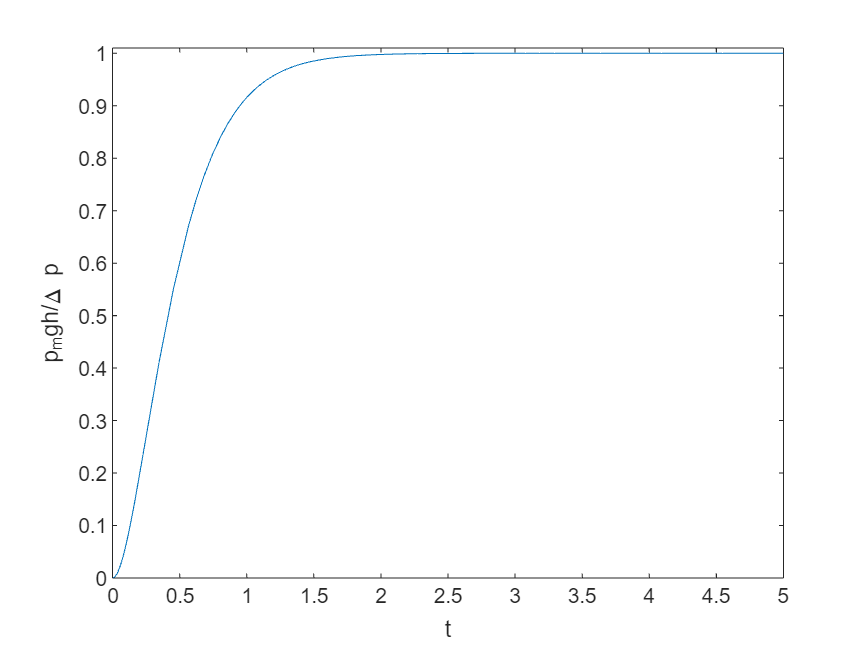

fplot(ySol)
xlim([0 5])
ylim([0 1.01])
title('Do thi')
xlabel("t")
ylabel("p_mgh/\Delta p")

close()

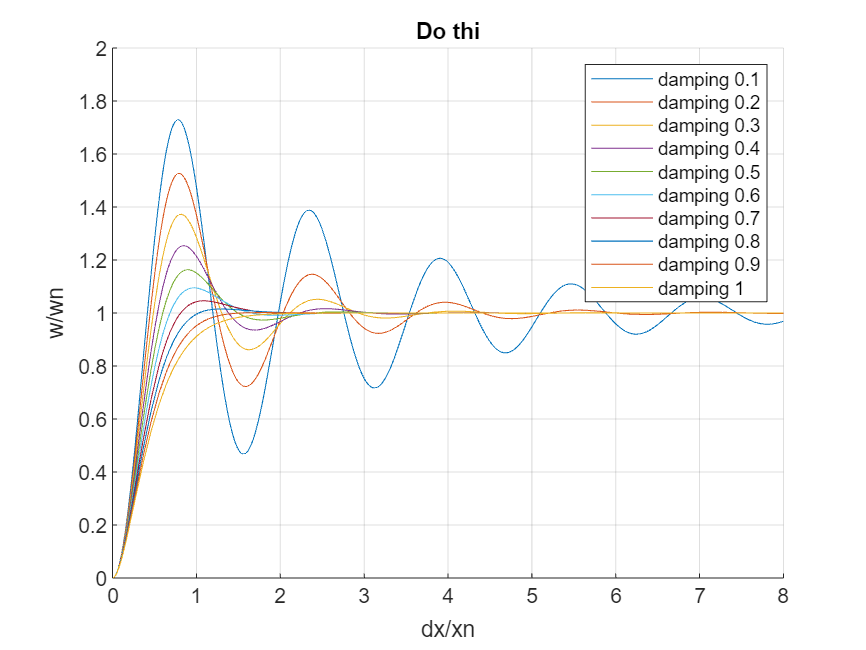

hold on
grid on
for dampv = .1:.1:1 
    b = 2*dampv*data.ct;
    ode = a*diff(y,x,2) + b*diff(y,x) + c*y - d == 0;
    Dy = diff(y,x,1);
    cond1 = y(0) == 0;
    cond2 = Dy(0) == 0;
    conds = [cond1 cond2];
    ySol(x) = dsolve(ode,conds);
    ySol = simplify(ySol)/d;
    name = 'damping '+string(dampv);
    fplot(ySol,'DisplayName',name)   
end
title('Do thi')
xlim([0 8])
ylim([0 2])
xlabel("t")
ylabel("p_mgh/\Delta p")
legend("show")